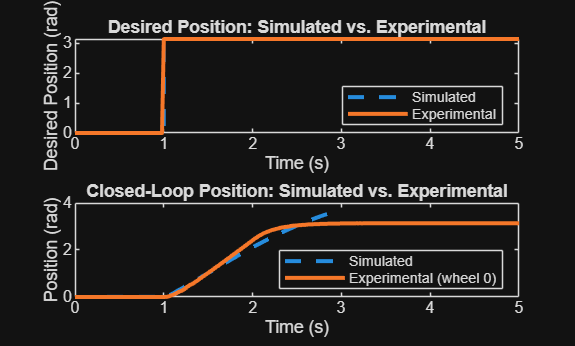

s = tf('s'); %% replaces transfer function in simulink, its not working there for some reason

%% Motor Model Parameters (from system ID, Section 3.3)
K = 0.364;      % DC gain [rad/Vs]
sigma = 18;     % time constant reciprocal [1/s]
Kp_vel = 11;    % proportional velocity gain, set inside the Velocity Subsystem

Kp = 5;     % error loop gain
Ki = 1;     % integral gain

%% Run Simulation
open_system('PI_control')     % open the Simulink model
out = sim('PI_control'); 

%%load experimental results
data = readmatrix('rawdata.txt');
%% Plot
figure
% Plot 1: Desired Position (commanded step, sim vs. Arduino)
subplot(2,1,1)
plot(out.DesiredPosition,'--','linewidth',2)
hold on
plot(data(:,1), data(:,2), 'linewidth', 2) % col1=time, col2=desired_pos[0]
legend('Simulated','Experimental','location','southeast')
hold off
xlabel('Time (s)')
ylabel('Desired Position (rad)')
title('Desired Position: Simulated vs. Experimental')

% Plot 2: Position (simulated position vs. actual wheel position)
subplot(2,1,2)
plot(out.Position,'--','linewidth',2)
hold on
plot(data(:,1), data(:,3), 'linewidth', 2) % col3=actual_pos[0]
legend('Simulated','Experimental (wheel 0)','location','southeast')
hold off
xlabel('Time (s)')
ylabel('Position (rad)')
title('Closed-Loop Position: Simulated vs. Experimental')


%% Interpretation
